# Handwritten Digits Classification using RBFN

clc;
clear;

## (a) Exact Interpolation Method

% load data and select classes: 
load './mnist_m.mat';

% select classes 7 and 9 (based on my matric number) and reassign label as "1";
class1 = 7;
class2 = 9;
Train_Label = double(train_classlabel == class1 | train_classlabel == class2);
Test_Label = double(test_classlabel == class1 | test_classlabel == class2);

Train_Data = train_data;
Test_Data = test_data;

Train_Idx = find(train_classlabel==class1 | train_classlabel==class2);
Test_Idx = find(test_classlabel==class1 | test_classlabel==class2);
class1_num = length(Train_Idx)+length(Test_Idx);

% evaluate performance
function [results, optimal_idx] = evaluate_performance(TrPred, TePred, TrLabel, TeLabel, results)
    %This generates 1,000 candidate thresholds spanning the full range of predictions (min(TrPred) to max(TrPred))
    num_thresholds= 1000;
    thresholds = linspace(min(TrPred), max(TrPred), num_thresholds+1);
    thresholds= thresholds(1:num_thresholds);

    TrN = length(TrLabel);
    TeN = length(TeLabel);
    
    for i = 1:num_thresholds
        % Predict Class 0 if the output < t, Class 1 if the output ≥ t
        t = thresholds(i);

        % Training set metrics
        TrPredClass = TrPred >= t;
        TN = sum(~TrPredClass & ~TrLabel');
        FP = sum(TrPredClass & ~TrLabel');
        FN = sum(~TrPredClass & TrLabel');
        TP = sum(TrPredClass & TrLabel');
        % Test set metrics
        TePredClass = TePred >= t;
        teTN = sum(~TePredClass & ~TeLabel');
        teFP = sum(TePredClass & ~TeLabel');
        teFN = sum(~TePredClass & TeLabel');
        teTP = sum(TePredClass & TeLabel');
        % Store results
        results.Thr(i)=t;
        results.TrAcc(i) = (TN + TP) / TrN;
        results.TeAcc(i) = (teTN + teTP) / TeN;
        results.ConfusionMatrices{i} = struct(...
            'Train', [TN FP; FN TP], ...
            'Test', [teTN teFP; teFN teTP]...
        );
    end

    % Find optimal threshold index
    [maxTeAcc, optimal_idx] = max(results.TeAcc);

    % Get optimal confusion matrices
    optimal_cm = results.ConfusionMatrices{optimal_idx};

    % Additional metrics display
    fprintf('Max TeAcc: %.4f%%\n', maxTeAcc*100);
    fprintf('Optimal Threshold: %.4f\n', thresholds(optimal_idx));
    
    fprintf('Training Precision: %.2f%%, Recall (TPR): %.2f%%, FPR: %.2f%%\n', ...
    100*optimal_cm.Train(2,2)/(optimal_cm.Train(2,2)+optimal_cm.Train(1,2)+eps), ...
    100*optimal_cm.Train(2,2)/(optimal_cm.Train(2,2)+optimal_cm.Train(2,1)+eps), ...
    100*optimal_cm.Train(1,2)/(optimal_cm.Train(1,2)+optimal_cm.Train(1,1)+eps));

    fprintf('Test Precision: %.2f%%, Recall (TPR): %.2f%%, FPR: %.2f%%\n', ...
    100*optimal_cm.Test(2,2)/(optimal_cm.Test(2,2)+optimal_cm.Test(1,2)), ...
    100*optimal_cm.Test(2,2)/(optimal_cm.Test(2,2)+optimal_cm.Test(2,1)), ...
    100*optimal_cm.Test(1,2)/(optimal_cm.Test(1,2)+optimal_cm.Test(1,1)));

    % Plot confusion matrices
    class_names = {'Class 0', 'Class 1'};
    plot_confusion_matrix(optimal_cm, class_names);
end

function plot_confusion_matrix(cm, class_names)
    figure('Position', [100 100 600 250]);
    
    % Training confusion matrix
    subplot(1,2,1);
    confusionchart(cm.Train, class_names);
    title('Training Set Confusion Matrix');
    
    % Test confusion matrix
    subplot(1,2,2);
    confusionchart(cm.Test, class_names);
    title('Test Set Confusion Matrix');
    
    % Formatting
    colormap(parula);
    set(gcf, 'Color', 'w');
end

λ=0.0000


Max TeAcc: 75.6000%
Optimal Threshold: 18.1818
Training Precision: 66.67%, Recall (TPR): 0.92%, FPR: 0.13%
Test Precision: 30.77%, Recall (TPR): 7.14%, FPR: 4.64%


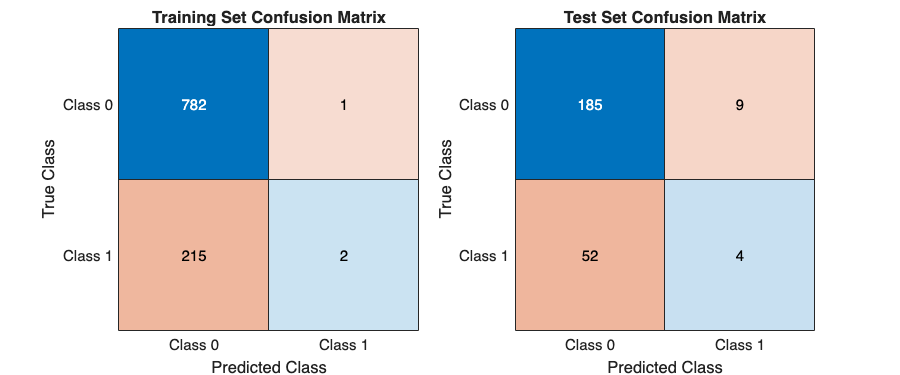

λ=0.0100


Max TeAcc: 78.0000%
Optimal Threshold: 0.2805
Training Precision: 42.22%, Recall (TPR): 17.51%, FPR: 6.64%
Test Precision: 52.17%, Recall (TPR): 21.43%, FPR: 5.67%


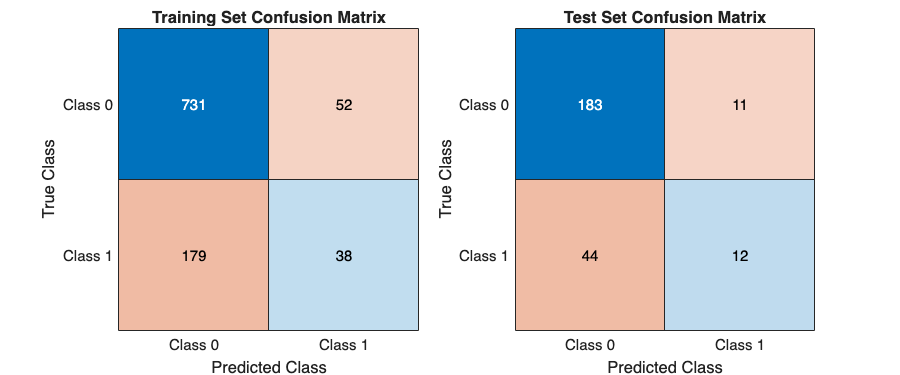

λ=0.1000


Max TeAcc: 80.0000%
Optimal Threshold: 0.2305
Training Precision: 54.46%, Recall (TPR): 25.35%, FPR: 5.87%
Test Precision: 60.71%, Recall (TPR): 30.36%, FPR: 5.67%


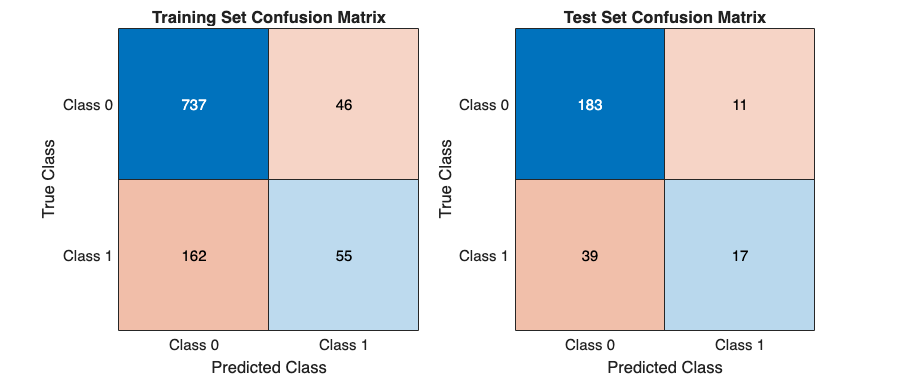

λ=1.0000


Max TeAcc: 78.8000%
Optimal Threshold: 0.2276
Training Precision: 48.28%, Recall (TPR): 6.45%, FPR: 1.92%
Test Precision: 80.00%, Recall (TPR): 7.14%, FPR: 0.52%


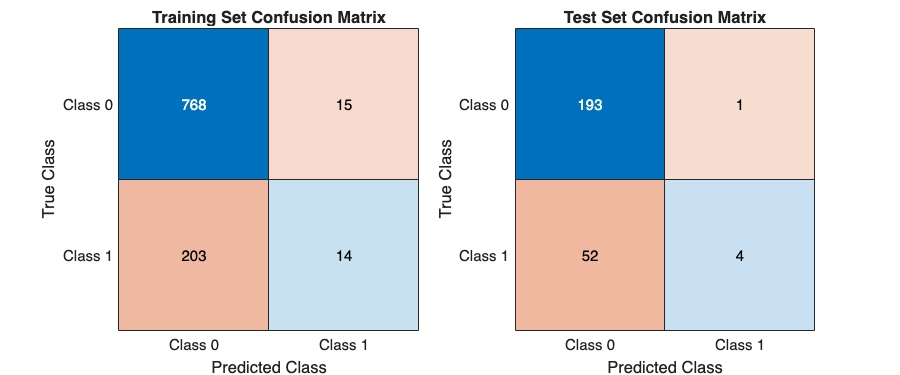

λ=10.0000


Max TeAcc: 78.4000%
Optimal Threshold: 0.2201
Training Precision: 39.39%, Recall (TPR): 5.99%, FPR: 2.55%
Test Precision: 75.00%, Recall (TPR): 5.36%, FPR: 0.52%


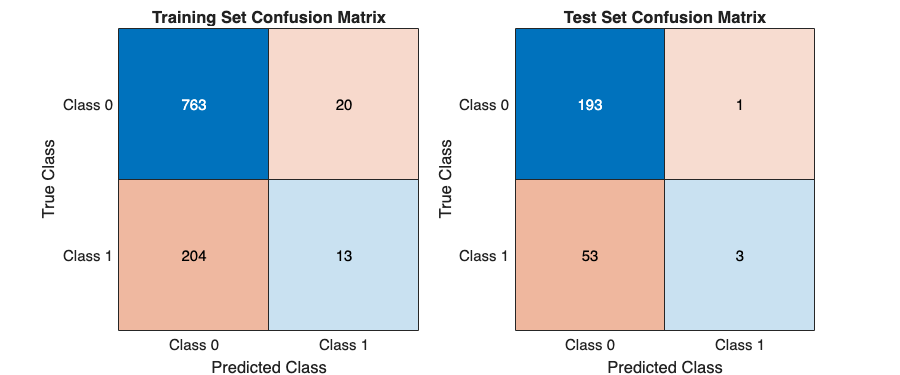

% build RBFN with sigma=100
sigma = 100;
lambda_values = [0, 1e-2, 0.1, 1, 10];

centers = Train_Data';  % Centers = training samples
Phi_train = exp(-pdist2(Train_Data', centers).^2 / (2*sigma^2));
Phi_test = exp(-pdist2(Test_Data', centers).^2/(2*sigma^2));

% solve with regularization
term1 = Phi_train' * Phi_train;
term2 = Phi_train' * Train_Label';

n =length(lambda_values);
num_thresholds = 1000;
% Preallocate memory
results = struct();
results.Thr = zeros(1, num_thresholds);
results.TrAcc = zeros(1, num_thresholds);
results.TeAcc = zeros(1, num_thresholds);
results.ConfusionMatrices = cell(num_thresholds, 1);
resultsArray = repmat(results, 1, n);
optimal_idx = cell(n);

for i = 1:n
    lambda = lambda_values(i);
    if lambda == 0
        w = Phi_train \ Train_Label'; % non-regularization
    else
        w = (term1 + lambda * eye(size(Phi_train,2)))\term2;
    end
    TrPred = Phi_train*w;
    TePred = Phi_test*w;
    
    % evaluate performance (different λ)
    fprintf('λ=%.4f\n', lambda);
    [resultsArray(i), optimal_idx{i}] = evaluate_performance(TrPred, TePred, Train_Label, Test_Label, resultsArray(i));
    resultsArray(i).lambda = lambda;
end

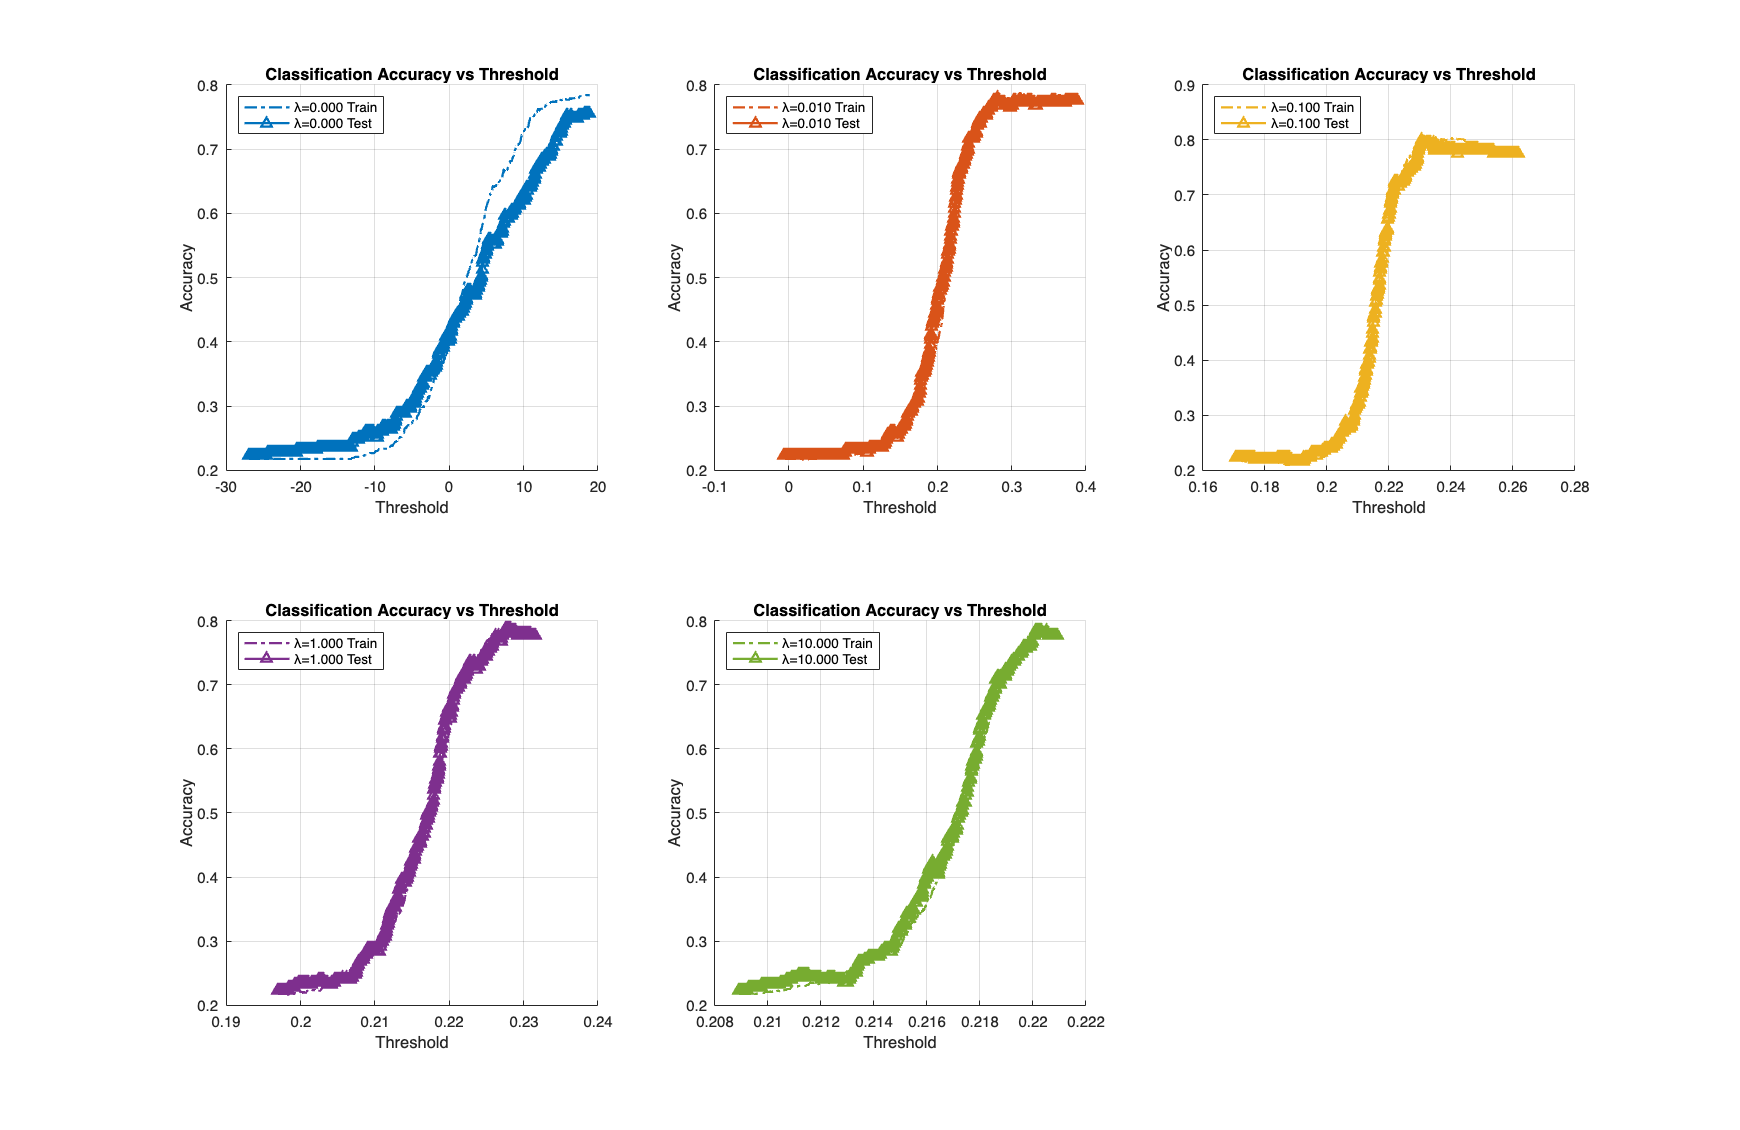

% Plot accuracy curve vs threshold (using different regularization parameters)
figure('Name', 'Classification Accuracy vs Threshold (changing λ)');
% set(gcf, 'position', [100 100 1200 500]);
screensize = get(0, 'screensize');
set(gcf, 'position', screensize);

% Accuracy curve
for i = 1:length(resultsArray)
    subplot(2,3,i);
    hold on;
    color_order = lines(n);
    plot(resultsArray(i).Thr,resultsArray(i).TrAcc,'-.','Color', color_order(i,:), 'LineWidth', 1.5);
    plot(resultsArray(i).Thr,resultsArray(i).TeAcc,'^-','Color', color_order(i,:), 'LineWidth', 1.5);
    legend(sprintf('λ=%.3f Train', lambda_values(i)), sprintf('λ=%.3f Test', lambda_values(i)));
    title('Classification Accuracy vs Threshold');
    xlabel('Threshold');
    ylabel('Accuracy');
    legend('Location','northwest');
    grid on;
    axis auto;
    hold off;
end

## (b) Fixed Centers Selected at Random

clear n lambda_values centers w Phi_train Phi_test term1 term2 TePred TrPred optimal_idx resultsArray;

## Part 1: Fixed Centers with Optimal Sigma

% randomly select 100 centers:
rng(2025);% For reproducibility
num_centers = 100;
center_idx = randperm(size(Train_Data,2), num_centers);
centers = Train_Data(:, center_idx)';

% Calculate d_max between selected centers
dist_matrix = pdist(centers); % Pairwise distances
d_max = max(dist_matrix);

% Optimal sigma calculation
sigma_recommended = d_max / sqrt(2*num_centers);

## Part 2: Sigma Parameter Sweep

σ=1.4227


Max TeAcc: 78.0000%
Optimal Threshold: 0.4848
Training Precision: 100.00%, Recall (TPR): 13.82%, FPR: 0.00%
Test Precision: 66.67%, Recall (TPR): 3.57%, FPR: 0.52%


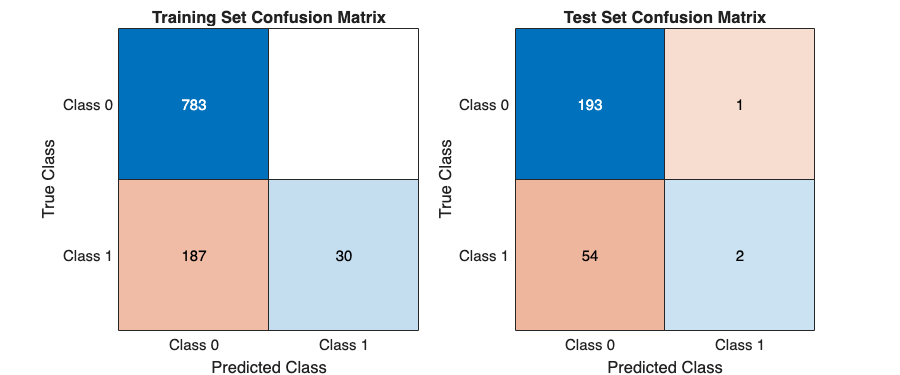

σ=0.1000


Max TeAcc: 77.6000%
Optimal Threshold: 0.0010
Training Precision: 100.00%, Recall (TPR): 11.52%, FPR: 0.00%
Test Precision: NaN%, Recall (TPR): 0.00%, FPR: 0.00%


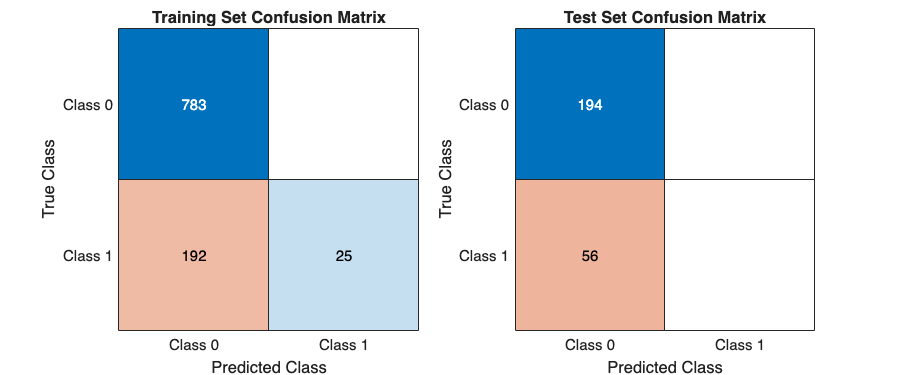

σ=1.0000


Max TeAcc: 77.6000%
Optimal Threshold: 0.2752
Training Precision: 71.11%, Recall (TPR): 14.75%, FPR: 1.66%
Test Precision: 50.00%, Recall (TPR): 5.36%, FPR: 1.55%


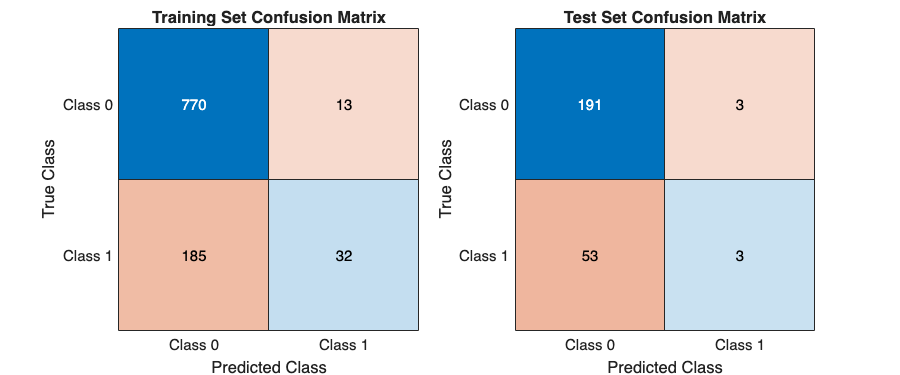

σ=10.0000


Max TeAcc: 83.6000%
Optimal Threshold: 0.4858
Training Precision: 90.82%, Recall (TPR): 41.01%, FPR: 1.15%
Test Precision: 82.61%, Recall (TPR): 33.93%, FPR: 2.06%


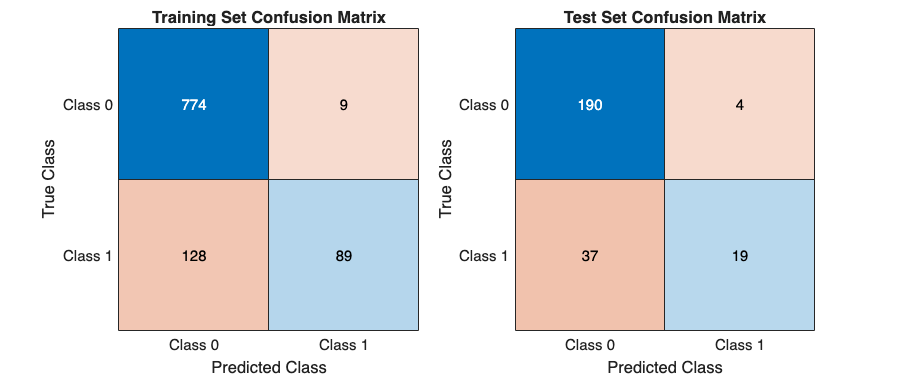

σ=100.0000


Max TeAcc: 79.6000%
Optimal Threshold: 0.3585
Training Precision: 68.54%, Recall (TPR): 28.11%, FPR: 3.58%
Test Precision: 64.71%, Recall (TPR): 19.64%, FPR: 3.09%


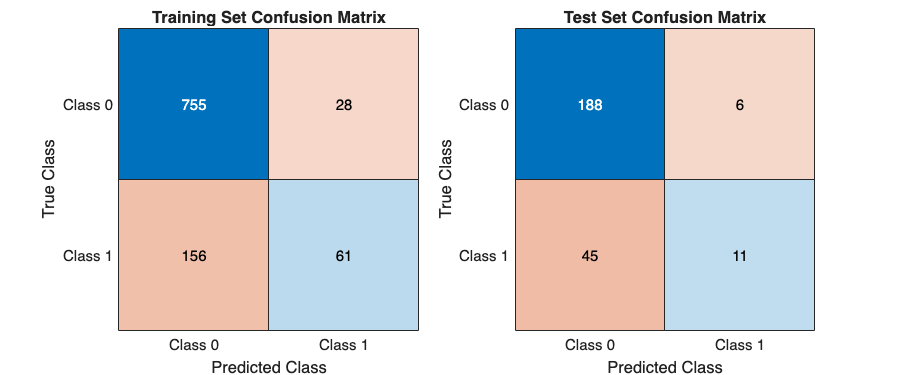

σ=1000.0000


Max TeAcc: 77.6000%
Optimal Threshold: 0.2170
Training Precision: 0.00%, Recall (TPR): 0.00%, FPR: 0.13%
Test Precision: NaN%, Recall (TPR): 0.00%, FPR: 0.00%


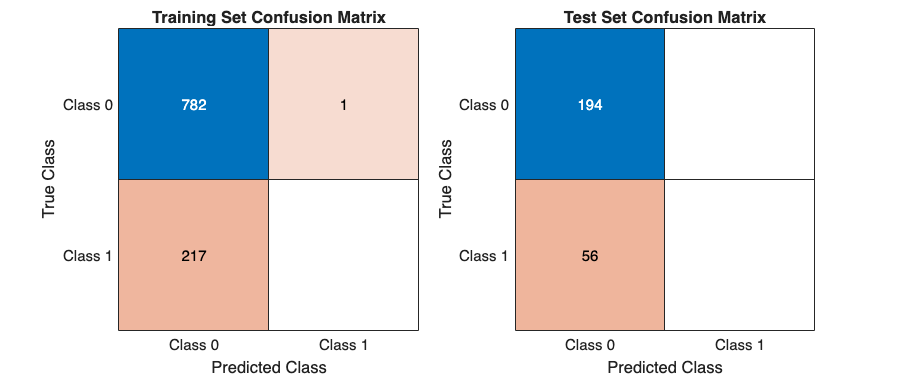

σ=10000.0000


Max TeAcc: 77.6000%
Optimal Threshold: 0.2170
Training Precision: 0.00%, Recall (TPR): 0.00%, FPR: 0.13%
Test Precision: NaN%, Recall (TPR): 0.00%, FPR: 0.00%


% Sigma range setup
sigma_values = [sigma_recommended, logspace(-1, 4, 6)]; % 0.1 to 10000 (6 points)
num_sigmas = length(sigma_values);

resultsArray = repmat(results, 1, num_sigmas);
optimal_idx = cell(num_sigmas);

%% Main Loop
for s = 1:num_sigmas
    sigma = sigma_values(s);
    % Calculate RBF features
    Phi_train = exp(-pdist2(Train_Data', centers).^2/(2*sigma^2));
    Phi_test = exp(-pdist2(Test_Data', centers).^2/(2*sigma^2));
    
    % Solve weights WITHOUT regularization
    w = Phi_train \ Train_Label';
    
    % Get predictions
    TrPred = Phi_train * w;
    TePred = Phi_test * w;
    
    % Evaluate performance
    fprintf('σ=%.4f\n', sigma);
    [resultsArray(s), optimal_idx{s}] = evaluate_performance(TrPred, TePred, Train_Label, Test_Label, resultsArray(s));
    resultsArray(s).sigma = sigma;
end

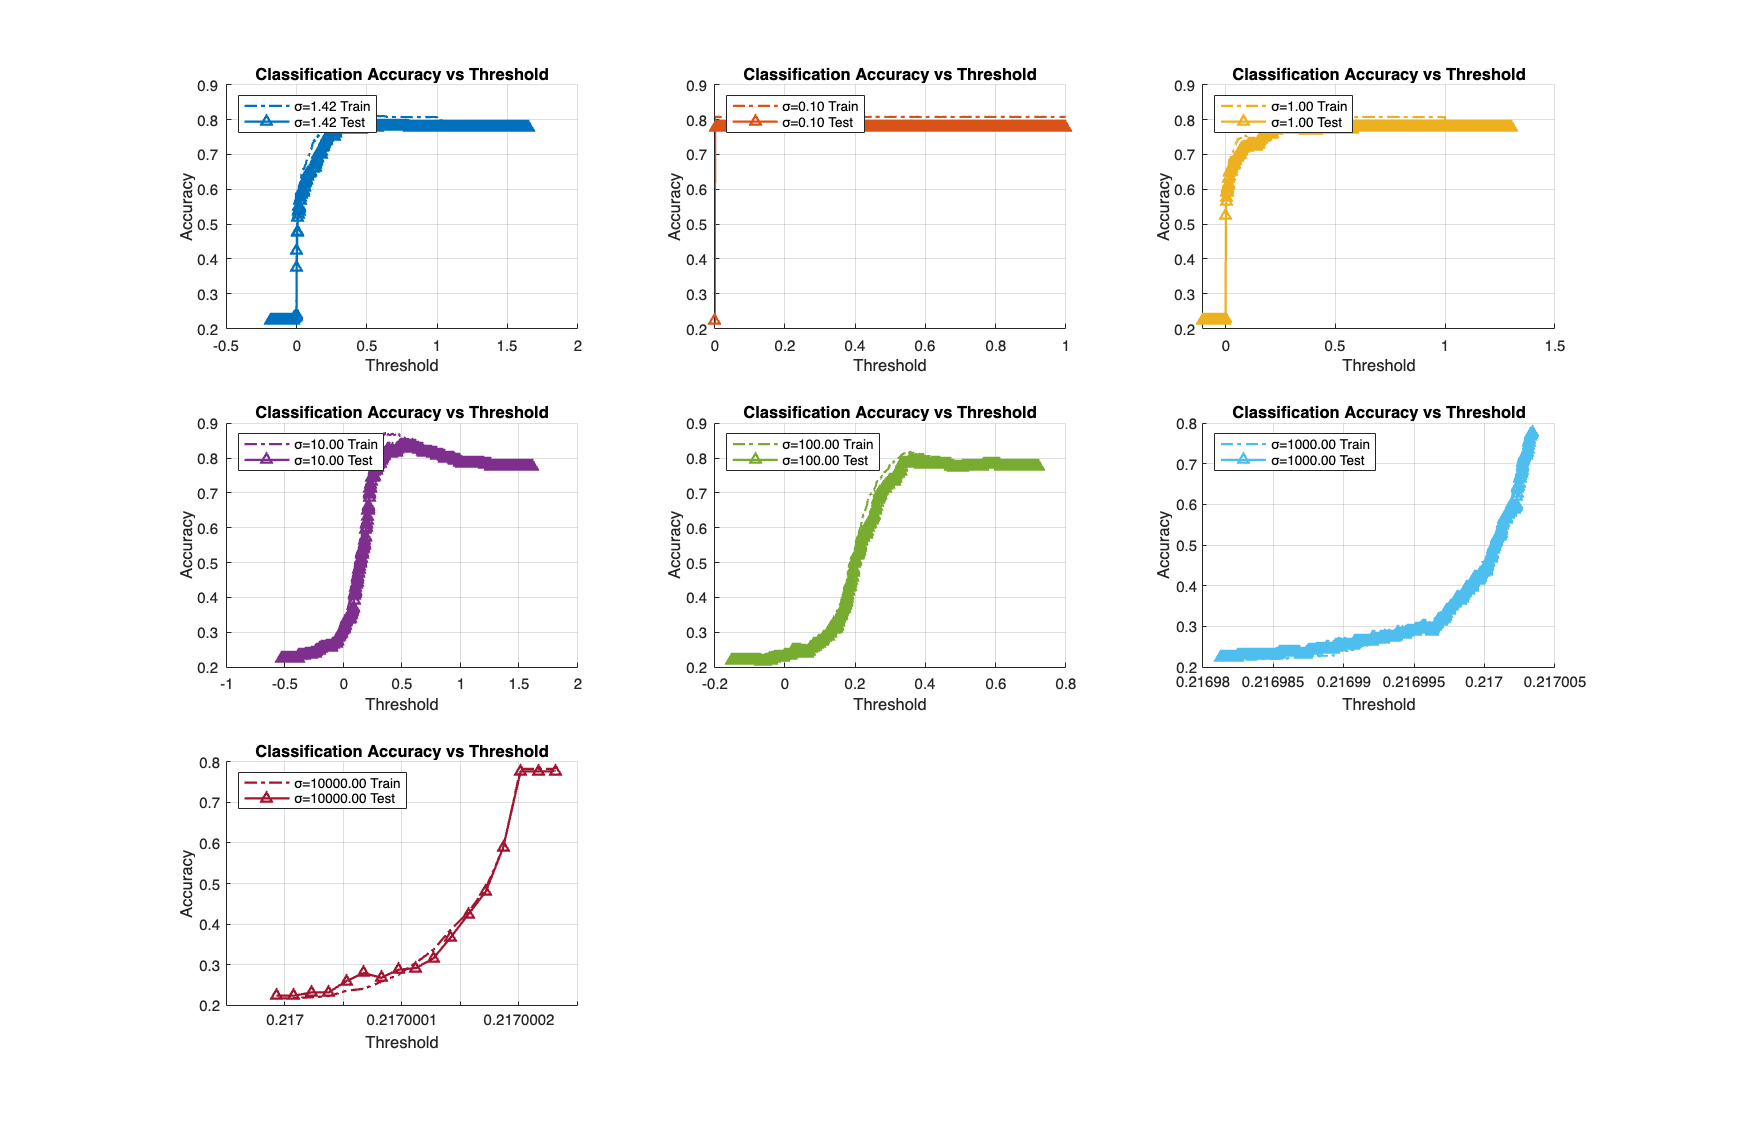

% Visualization
% Plot accuracy curve vs threshold (using different sigma)
figure('Name', 'Classification Accuracy vs Threshold (changing σ)');
screensize = get(0, 'screensize');
set(gcf, 'position', screensize);

% Accuracy curve
for s = 1:length(resultsArray)
    rows = floor(sqrt(num_sigmas))+1;
    subplot(rows,ceil(num_sigmas/rows),s);
    hold on;
    color_order = lines(num_sigmas);
    plot(resultsArray(s).Thr,resultsArray(s).TrAcc,'-.','Color', color_order(s,:), 'LineWidth', 1.5);
    plot(resultsArray(s).Thr,resultsArray(s).TeAcc,'^-','Color', color_order(s,:), 'LineWidth', 1.5);
    legend(sprintf('σ=%.2f Train', sigma_values(s)), sprintf('σ=%.2f Test', sigma_values(s)));
    title('Classification Accuracy vs Threshold');
    xlabel('Threshold');
    ylabel('Accuracy');
    legend('Location','northwest');
    grid on;
    axis auto;
    hold off;
end

## (c) K-Means Clustering

% % figure;
% %% 预处理：前景增强与背景抑制
% processed_data = zeros(size(Train_Data));
% parfor i = 1:size(Train_Data,2)
%     % 1. 自适应阈值二值化（区分前景背景）
%     img = reshape(Train_Data(:,i), 28, 28);
%     binary_mask = imbinarize(img, 'global');
% 
%     % 2. 形态学操作去噪
%     cleaned_mask = bwareaopen(binary_mask, 10); % 移除小面积噪声
% 
%     % 3. 保留前景像素，背景置零
%     processed_img = img .* cleaned_mask;
% 
%     % % 4. 提取HOG特征（替代原始像素）
%     % hogFeatures = extractHOGFeatures(processed_img, ...
%     %     'CellSize', [4 4], ...
%     %     'BlockSize', [2 2], ...
%     %     'NumBins', 9);
% 
%     processed_data(:,i) = reshape(processed_img,784,1);
%     % subplot(1,2,1);imshow(img);
%     % subplot(1,2,2);imshow(processed_img);
% end

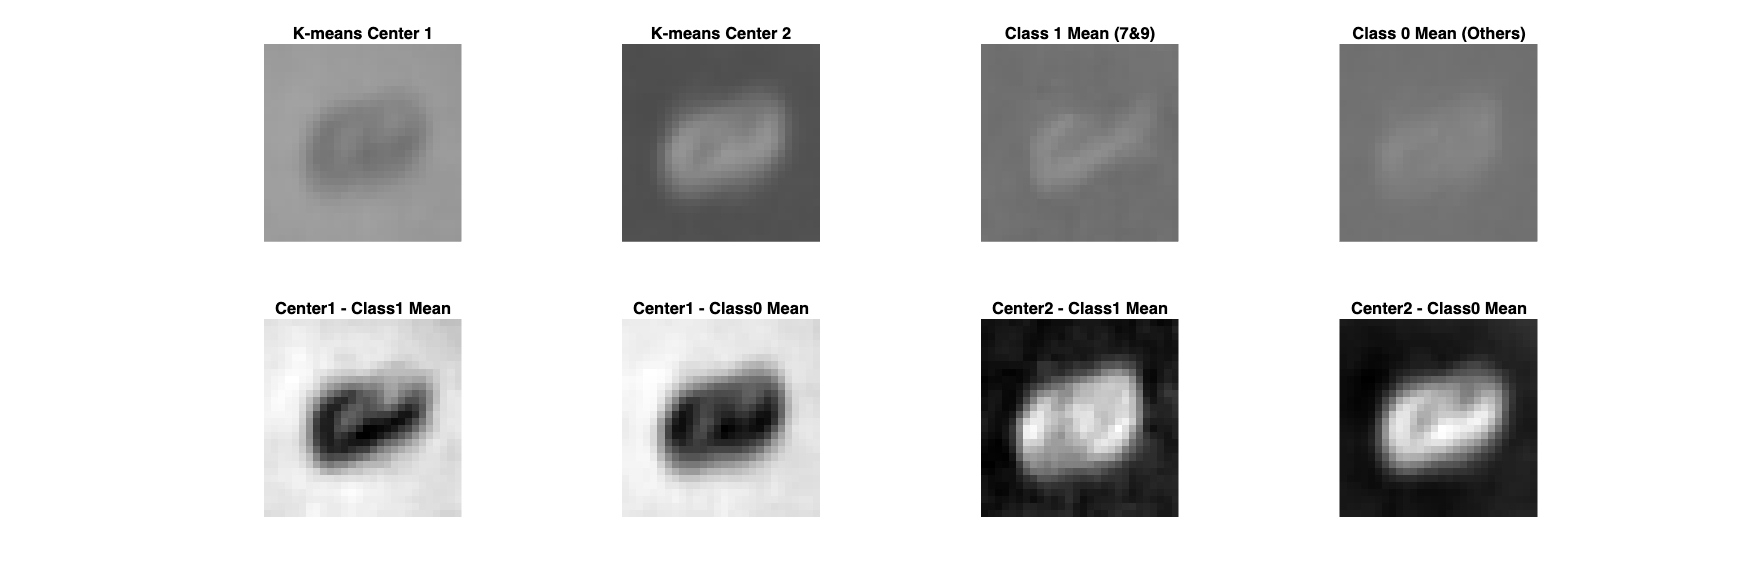

clear num_sigmas sigma_values centers w Phi_train Phi_test TePred TrPred optimal_idx resultsArray;
%% Compute Class Means
% Get class indices
pos_idx = find(Train_Label == 1);  % Positive class (digits 7 & 9)
neg_idx = find(Train_Label == 0);  % Negative class (other digits)

% Compute mean images
mean_pos = mean(Train_Data(:, pos_idx), 2);
mean_neg = mean(Train_Data(:, neg_idx), 2);

% figure;
% subplot(1,2,1);imshow(reshape(Train_Data(:, pos_idx(3)),28,28));
% subplot(1,2,2);imshow(reshape(Train_Data(:, neg_idx(3)),28,28));

% K-means clustering
num_clusters = 2;
rng(2025);
[~, centers] = kmeans(Train_Data', num_clusters, 'MaxIter', 1000, 'Replicates', 5);

%% Visualization
figure('Position', [100 100 1200 400])

% K-means centers
subplot(2,4,1)
imshow(reshape(centers(1,:),28,28))
title('K-means Center 1')

subplot(2,4,2)
imshow(reshape(centers(2,:),28,28))
title('K-means Center 2')

% Class means
subplot(2,4,3)
imshow(reshape(mean_pos,28,28))
title('Class 1 Mean (7&9)')

subplot(2,4,4)
imshow(reshape(mean_neg,28,28))
title('Class 0 Mean (Others)')

% Difference visualization
subplot(2,4,5)
imshow(reshape(centers(1,:)-mean_pos',28,28), [])
title('Center1 - Class1 Mean')

subplot(2,4,6)
imshow(reshape(centers(1,:)-mean_neg',28,28), [])
title('Center1 - Class0 Mean')

subplot(2,4,7)
imshow(reshape(centers(2,:)-mean_pos',28,28), [])
title('Center2 - Class1 Mean')

subplot(2,4,8)
imshow(reshape(centers(2,:)-mean_neg',28,28), [])
title('Center2 - Class0 Mean')

% find optimal threshold (based on F1-Score)
function [results, optimal_threshold, metrics] = find_optimal_threshold_adv(TrPred,TePred,TrLabel,TeLabel,results)
    num_thresh= 1000;
    thresholds = linspace(min(TrPred), max(TrPred), num_thresh+1);
    thresholds= thresholds(1:num_thresh);

    TrN = length(TrLabel);
    TeN = length(TeLabel);

    metrics = struct(...
        'threshold', num2cell(thresholds),...
        'precision', zeros(num_thresh,1),...
        'recall', zeros(num_thresh,1),...
        'specificity', zeros(num_thresh,1),...
        'f1', zeros(num_thresh,1),...
        'gmean', zeros(num_thresh,1),...
        'youden', zeros(num_thresh,1));

    for i = 1:num_thresh
        t = thresholds(i);
        % Training set metrics
        TrPredClass = TrPred >= t;
        TN = sum(~TrPredClass & ~TrLabel');
        FP = sum(TrPredClass & ~TrLabel');
        FN = sum(~TrPredClass & TrLabel');
        TP = sum(TrPredClass & TrLabel');
        % Test set metrics
        TePredClass = TePred >= t;
        teTN = sum(~TePredClass & ~TeLabel');
        teFP = sum(TePredClass & ~TeLabel');
        teFN = sum(~TePredClass & TeLabel');
        teTP = sum(TePredClass & TeLabel');
        
        % Store results(FOR COMPARISION)
        results.Thr(i)=t;
        results.TrAcc(i) = (TN + TP) / TrN;
        results.TeAcc(i) = (teTN + teTP) / TeN;
        results.ConfusionMatrices{i} = struct(...
            'Train', [TN FP; FN TP], ...
            'Test', [teTN teFP; teFN teTP]...
        );

        % Store metrics(FOR OPTIMAL THRESHOLD)
        metrics(i).precision = TP/(TP + FP + eps);
        metrics(i).recall = TP/(TP + FN + eps);
        metrics(i).specificity = TN/(TN + FP + eps);
        metrics(i).f1 = 2*(metrics(i).precision*metrics(i).recall)/...
                        (metrics(i).precision + metrics(i).recall + eps);
        metrics(i).gmean = sqrt(metrics(i).recall * metrics(i).specificity);
        metrics(i).youden = metrics(i).recall + metrics(i).specificity - 1;
    end
    
    % find optimal threshold in terms of metrics
    [~, idx_acc] = max(results.TeAcc);
    [~, idx_f1] = max([metrics.f1]);
    [~, idx_gmean] = max([metrics.gmean]);
    [~, idx_youden] = max([metrics.youden]);

    opt_idx = idx_acc;

    % Additional metrics display
    fprintf('Optimal Threshold: %.4f,Test accuracy: %.4f%%, F1-Score: %.4f, G-Mean: %.4f, Youden''s J: %.4f\n',... 
        thresholds(opt_idx), 100*results.TeAcc(opt_idx), metrics(opt_idx).f1, metrics(opt_idx).gmean, metrics(opt_idx).youden);

    optimal_threshold = struct(...
        'f1', thresholds(idx_f1),...
        'gmean', thresholds(idx_gmean),...
        'youden', thresholds(idx_youden));

    % Get optimal confusion matrices
    optimal_cm = results.ConfusionMatrices{opt_idx};

    fprintf('Training Precision: %.2f%%, Recall (TPR): %.2f%%, FPR: %.2f%%\n', ...
    100*metrics(opt_idx).precision, ...
    100*metrics(opt_idx).recall, ...
    100*(1-metrics(opt_idx).specificity));

    fprintf('Test Precision: %.2f%%, Recall (TPR): %.2f%%, FPR: %.2f%%\n', ...
    100*optimal_cm.Test(2,2)/(optimal_cm.Test(2,2)+optimal_cm.Test(1,2)), ...
    100*optimal_cm.Test(2,2)/(optimal_cm.Test(2,2)+optimal_cm.Test(2,1)), ...
    100*optimal_cm.Test(1,2)/(optimal_cm.Test(1,2)+optimal_cm.Test(1,1)));

    % Plot confusion matrices
    class_names = {'Class 0', 'Class 1'};
    plot_confusion_matrix(optimal_cm, class_names);
 end

## Train RBF Network and Evaluation

Optimal Threshold: 0.3072,Test accuracy: 77.6000%, F1-Score: 0.0088, G-Mean: 0.0674, Youden's J: -0.0082
Training Precision: 9.09%, Recall (TPR): 0.46%, FPR: 1.28%
Test Precision: NaN%, Recall (TPR): 0.00%, FPR: 0.00%


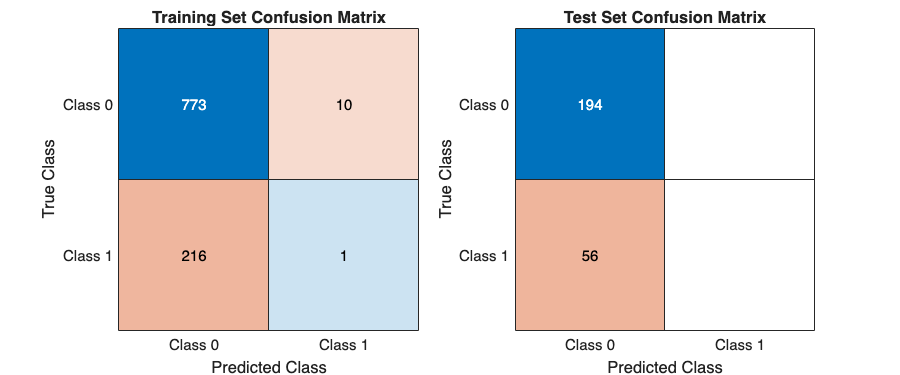

% Calculate sigma (based on center distance)
% centers = [mean_pos';mean_neg'];% if use means as centers?
d_max = norm(centers(1,:)-centers(2,:));
sigma = d_max/sqrt(2*num_clusters);

% d_class0_class1 = norm(mean_pos-mean_neg);
% sigma = d_class0_class1;

% Construct RBF feature matrix
Phi_train = exp(-pdist2(Train_Data', centers).^2/(2*sigma^2));
Phi_test = exp(-pdist2(Test_Data', centers).^2/(2*sigma^2));

% Solve weights (without regularization)
w = Phi_train \ Train_Label';

% Prediction and evaluation
TrPred = Phi_train * w;
TePred = Phi_test * w;

[results,optimal_threshold, metrics] = find_optimal_threshold_adv(TrPred, TePred, Train_Label, Test_Label, results);

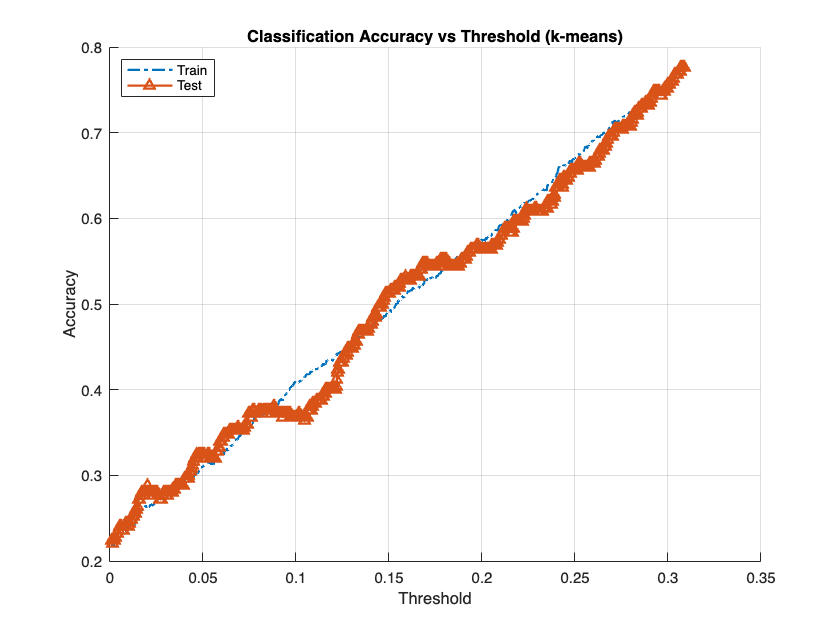

% [results, optimal_idx] = evaluate_performance(TrPred, TePred, Train_Label, Test_Label, results);
    
% Visualization
figure('Name', 'Classification Accuracy vs Threshold (k-means)');
hold on;
plot(results.Thr,results.TrAcc,'-.', 'LineWidth', 1.5);
plot(results.Thr,results.TeAcc,'^-', 'LineWidth', 1.5);
legend('Train', 'Test');
title('Classification Accuracy vs Threshold (k-means)');
xlabel('Threshold');
ylabel('Accuracy');
legend('Location','northwest');
grid on;
axis auto;

## Quantitative Analysis

% Helper Function
function [corr_coef, euclidean_dist] = calc_similarity(vec1, vec2)
    % Calculate Pearson correlation and Euclidean distance
    corr_coef = corr(vec1(:), vec2(:));
    euclidean_dist = norm(vec1 - vec2);
end

% Calculate similarity metrics
similarity_metrics = struct();

% Similarity between Center1 and positive class mean
[similarity_metrics.center1_pos_corr, similarity_metrics.center1_pos_dist] = ...
    calc_similarity(centers(1,:), mean_pos);

% Similarity between Center1 and negative class mean 
[similarity_metrics.center1_neg_corr, similarity_metrics.center1_neg_dist] = ...
    calc_similarity(centers(1,:), mean_neg);

% Similarity between Center2 and positive class mean
[similarity_metrics.center2_pos_corr, similarity_metrics.center2_pos_dist] = ...
    calc_similarity(centers(2,:), mean_pos);

% Similarity between Center2 and negative class mean
[similarity_metrics.center2_neg_corr, similarity_metrics.center2_neg_dist] = ...
    calc_similarity(centers(2,:), mean_neg);

% Display results
disp(struct2table(similarity_metrics))

    center1_pos_corr    center1_pos_dist    center1_neg_corr    center1_neg_dist    center2_pos_corr    center2_pos_dist    center2_neg_corr    center2_neg_dist
    ________________    ________________    ________________    ________________    ________________    ________________    ________________    ________________

        -0.83482             108.31             -0.91161             102.42             0.87014              94.982             0.96916              98.675     

